binDataFile = fopen("storage/storage.bin","r");

nElem = fread(binDataFile,1,"uint32");
fseek(binDataFile, 0x1000,"bof");

data = fread(binDataFile,14*nElem,"float32");
data = reshape(data,14,[]);
timedata = array2timetable(data(2:end,:)',"RowTimes",seconds(data(1,:)'));
fclose(binDataFile);

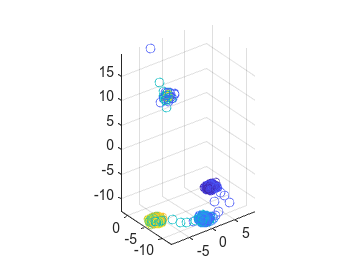

figure
scatter3(data(8,:),data(9,:), data(10,:),'CData', data(1,:))
hold on
scatter3(data(2,:),data(3,:), data(4,:), 'CData',data(1,:))
axis equal

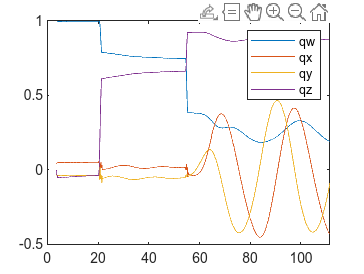

figure
plot(data(1,:),data(11,:))
hold on
plot(data(1,:),data(12,:))
plot(data(1,:),data(13,:))
plot(data(1,:),data(14,:))
legend("qw","qx","qy","qz")

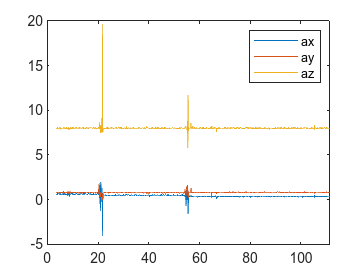

figure
plot(data(1,:),data(2,:))
hold on
plot(data(1,:),data(3,:))
plot(data(1,:),data(4,:))
legend("ax","ay","az")

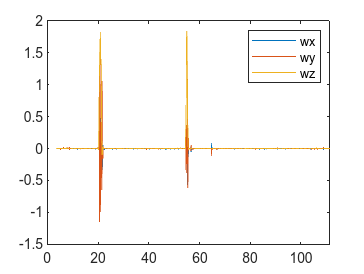

figure
plot(data(1,:),data(5,:))
hold on
plot(data(1,:),data(6,:))
plot(data(1,:),data(7,:))
legend("wx","wy","wz")

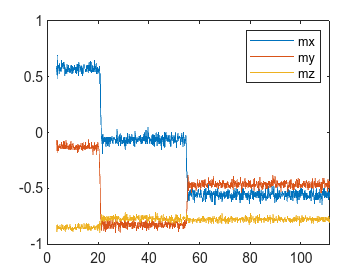

figure
norm = sqrt(data(8,100)*data(8,100)+data(9,100)*data(9,100)+data(10,100)*data(10,100));
plot(data(1,:),data(8,:)/norm)
hold on
plot(data(1,:),data(9,:)/norm)
plot(data(1,:),data(10,:)/norm)
legend("mx","my","mz")

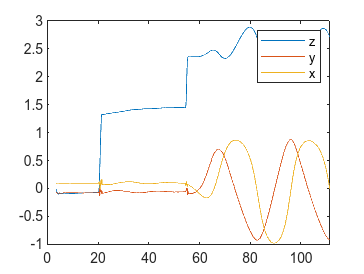

quats = quaternion(data(11:14,:)');
euls = quats.euler("ZYX","point");
figure
plot(data(1,:),euls(:,1));
hold on
plot(data(1,:),euls(:,2));
plot(data(1,:),euls(:,3));
legend("z","y","x");


% % Create an Aero.Animation object
% hAnim = Aero.Animation;
% 
% % Create the aircraft body using a geometry file (e.g., an AC3D file).
% % Replace 'yourAircraft.ac' with your aircraft model file.
% hAnim.createBody('pa24-250_orange.ac','Ac3d');
% 
% % Extract quaternion data and convert to Euler angles.
% % MATLAB’s quat2eul returns [yaw, pitch, roll] (in radians) for a quaternion [w x y z].
% quatData = timedata{:, {'Var10','Var11','Var12','Var13'}};
% eul = quaternion(quatData).euler("ZYX","point");  % [yaw, pitch, roll] in radians
% 
% % Create a 6DoF matrix. Here, we assume no position change so we set [x y z] to zeros.
% % Rearrange Euler angles to [roll, pitch, yaw] as required.
% numSamples = height(timedata);
% data6DoF = [seconds(timedata.Time), zeros(numSamples,3), eul(:,3), eul(:,2), eul(:,1)];
% 
% % Assign the data to the animation object:
% hAnim.Bodies{1}.TimeSeriesSourceType = 'Array6DoF';
% hAnim.Bodies{1}.TimeSeriesSource = data6DoF;
% 
% 
% % (Optional) Adjust camera settings if desired.
% hAnim.Camera.PositionFcn = @staticCameraPosition;
% hAnim.Figure.Position(1) = hAnim.Figure.Position(1) + 572/2;
% 
% % Initialize the animation at the start time
% startTime = timedata.Time(1);
% hAnim.updateBodies(seconds(startTime));
% hAnim.updateCamera(seconds(startTime));
% hAnim.show();
% 
% % Animate through the data
% for k = 1:length(timedata.Time)
%     currentTime = seconds(timedata.Time(k));
%     hAnim.updateBodies(currentTime);
%     hAnim.updateCamera(currentTime);
%     drawnow;  % refresh the figure
%     pause(0.001);  % adjust pause for desired speed
% end


% [A,b] = magcal(data(8:10,1:400)')
% Afile = fopen("calibration/A_mag_cal.bin","w");
% fwrite(Afile,A,"float32");
% bfile = fopen("calibration/b_mag_cal.bin","w");
% fwrite(bfile,b,"float32");
% 
% fclose(Afile);
% fclose(bfile);